# Matpower Simulation - 6 bus grid with fault

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a standard testbed. 

clear all
close all
clc
rng(11);

We load the data and we define the simulation setup to be used.

define_constants;
samples = 100;
noise_v_sd = 0;
noise_i_sd = 1e-4;
random_load_power_cv = 0.1;
fault_instant = 50;
mpc_initial = loadcase('case6ww_modified');

Error using loadcase (line 190)
loadcase: specified case not in MATLAB's search path

mpc_after_fault = mpc_initial;
mpc_after_fault.branch(7, :) = [];

We define useful constants and we derive the impedence matrix.

Y = full(makeYbus(mpc_initial));
Y_after_fault = full(makeYbus(mpc_after_fault)); 
load_mask = mpc_initial.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc_initial.bus(:, BUS_TYPE) == PV;
n = size(mpc_initial.bus, 1);
n_gen = size(mpc_initial.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;

We check admittance matrices before and after the fault

matrix_heatmap(Y, 'Real Y');
matrix_heatmap(Y_after_fault, 'Real Y after fault');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))
issymmetric(Y)

Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles.

load_avg_pd = mpc_initial.bus(load_mask, PD);
load_avg_qd = mpc_initial.bus(load_mask, QD);
mpc = mpc_initial;
for i = 1:samples
    if i == fault_instant
        mpc = mpc_after_fault;
    end
    mpc.bus(load_mask, PD) = normrnd(load_avg_pd, random_load_power_cv * load_avg_pd);
    mpc.bus(load_mask, QD) = normrnd(load_avg_qd, random_load_power_cv * load_avg_qd);
    res = runpf(mpc);
    bus_phase = res.bus(:, VA) * pi / 180;
    bus_magnitude = res.bus(:, VM);
    bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
    load_pd(:, i) = res.bus(load_mask, PD);
    load_qd(:, i) = res.bus(load_mask, QD);
end


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.27 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    200.1             173.5
Loads              3     Load                   194.1             155.2
  Fixed            3       Fixed                194.1             155.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));
bus_current = zeros(size(bus_voltage));
bus_current(:, 1:fault_instant-1) = Y * bus_voltage(:, 1:fault_instant-1) + ei(:, 1:fault_instant-1);
bus_current(:, fault_instant:end) = Y_after_fault * bus_voltage(:, fault_instant:end) + ei(:, fault_instant:end);
bus_voltage = bus_voltage + ev;
Y_real = zeros([n n samples]);
Y_real(:, :, 1:fault_instant-1) = repmat(Y, 1, 1, fault_instant-1);
Y_real(:, :, fault_instant:end) = repmat(Y_after_fault, 1, 1, samples - fault_instant + 1);

We visualize the evolution of the voltage and the current for a random node.

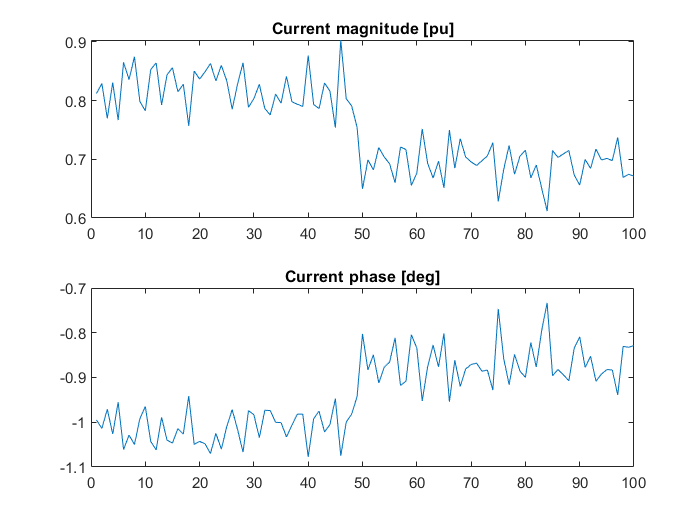

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title('Current magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title('Current phase [deg]');

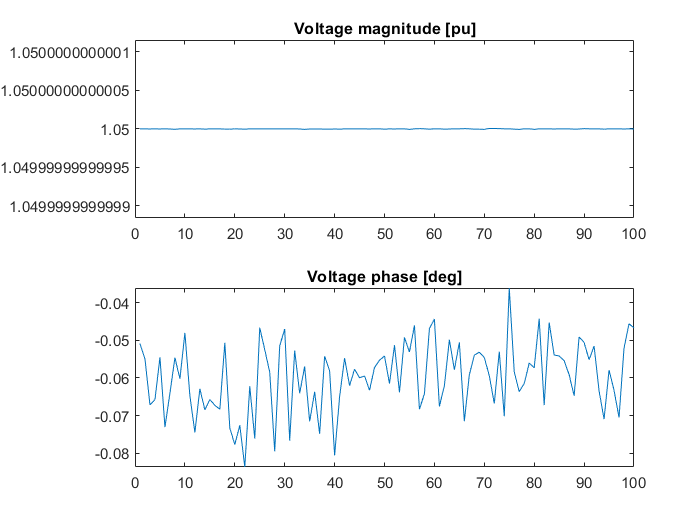

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_voltage));
title('Voltage magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_voltage));
title('Voltage phase [deg]');

Moreover, we check correlation between voltages

corr(bus_voltage')

ans =    1.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i   1.0000 + 0.0000i   0.4010 + 0.0110i   0.8492 + 0.0885i   0.6037 + 0.0440i   0.2424 - 0.0442i
  -0.0000 - 0.0000i   0.4010 - 0.0110i   1.0000 + 0.0000i   0.4677 + 0.0063i   0.8741 + 0.1459i   0.9316 + 0.2496i
  -0.0000 + 0.0000i   0.8492 - 0.0885i   0.4677 - 0.0063i   1.0000 + 0.0000i   0.6172 + 0.0220i   0.3220 + 0.0062i
  -0.0000 + 0.0000i   0.6037 - 0.0440i   0.8741 - 0.1459i   0.6172 - 0.0220i   1.0000 + 0.0000i   0.8215 + 0.0387i
  -0.0000 - 0.0000i   0.2424 + 0.0442i   0.9316 - 0.2496i   0.3220 - 0.0062i   0.8215 - 0.0387i   1.0000 + 0.0000i


## Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

## RLS with symmetricity constraints (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

lambda = 0.7;
D = duplication_matrix(n);
[Y1_hat, Z1_hat] = estimate_rls(bus_voltage, bus_current, D, lambda);

Completed iteration 100


Froebius norm for RLS1 - up to fault is 0.062953
Max norm for RLS1 - up to fault is 0.024049


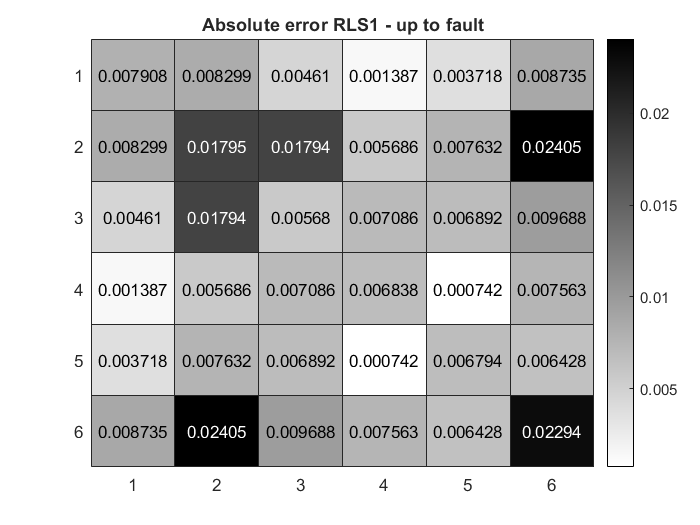

error_metrics(Y, Y1_hat(:, :, fault_instant-1), 'RLS1 - up to fault');

Froebius norm for RLS1 - after fault is 0.087715
Max norm for RLS1 - after fault is 0.057914


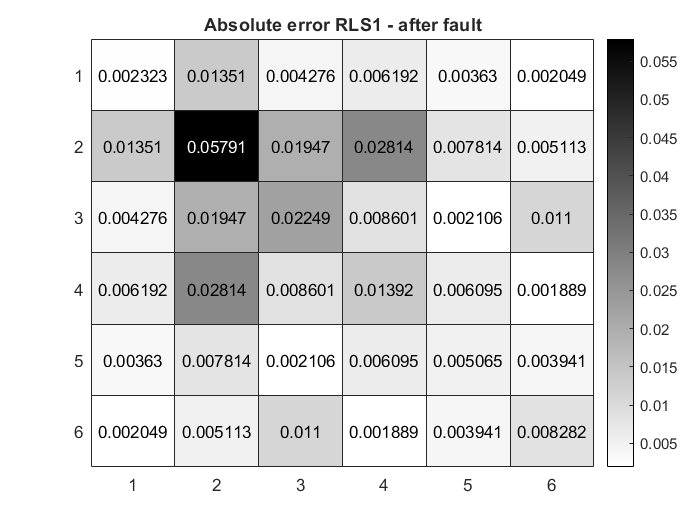

error_metrics(Y_after_fault, Y1_hat(:, :, end), 'RLS1 - after fault');

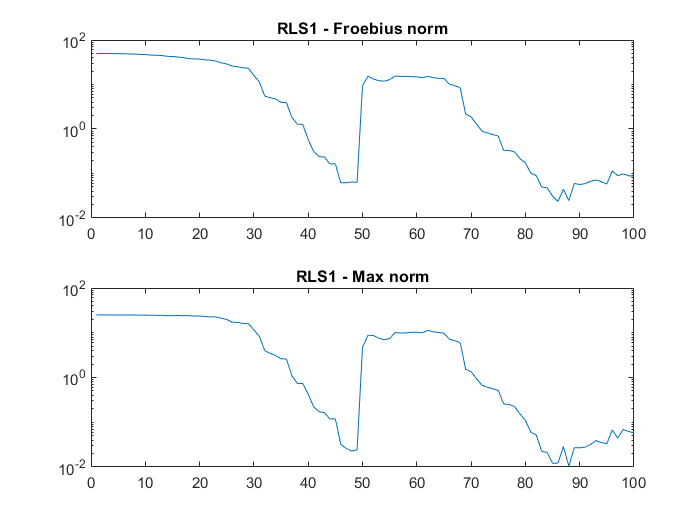

[rls1_foeb, rls1_max] = error_evolution(Y_real, Y1_hat, 'RLS1');

## RLS2

Then, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

Q = D * transformation_matrix(n);
[Y2_hat, Z2_hat] = estimate_rls(bus_voltage, bus_current, Q, lambda);

Completed iteration 100


Froebius norm for RLS2 - up to fault is 0.03576
Max norm for RLS2 - up to fault is 0.013347


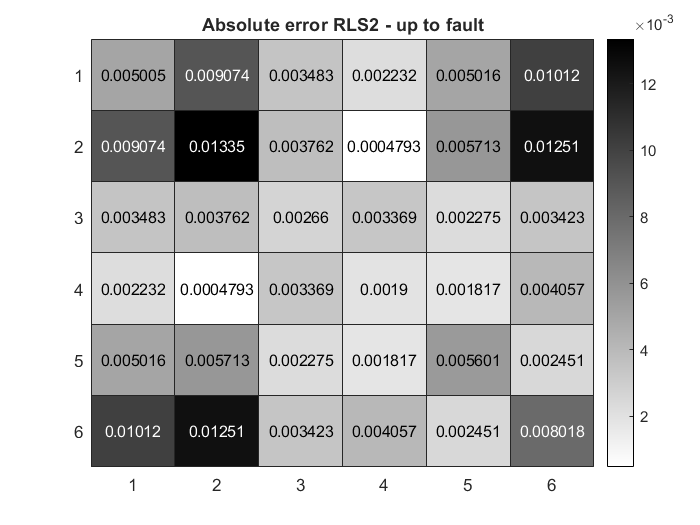

error_metrics(Y, Y2_hat(:, :, fault_instant-1), 'RLS2 - up to fault');

Froebius norm for RLS2 - after fault is 0.065006
Max norm for RLS2 - after fault is 0.038386


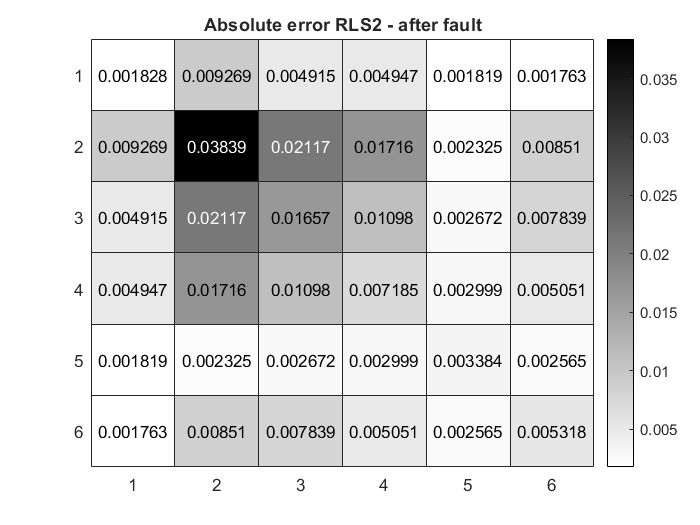

error_metrics(Y_after_fault, Y2_hat(:, :, end), 'RLS2 - after fault');

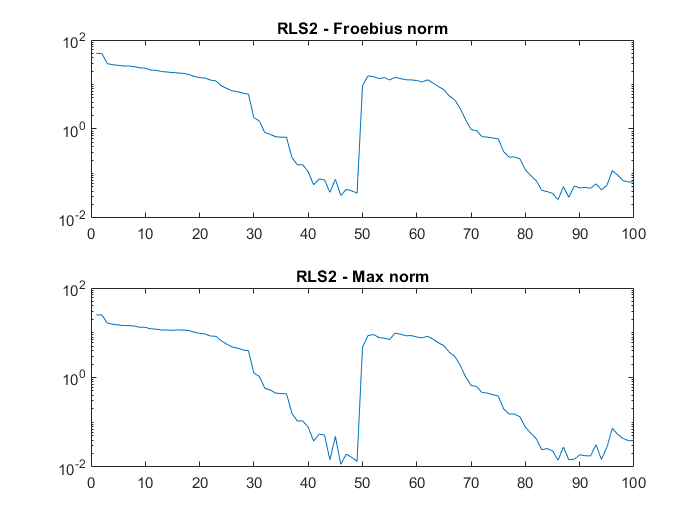

[rls2_foeb, rls2_max] = error_evolution(Y_real, Y2_hat, 'RLS2');

## RLS with DoE

Finally, we integrate Design of Experiment into our framework

x0_doe = 0.1 * ones([size(Q, 2) 1]);
Z0_doe = 100 * eye(size(Q, 2));
[Y_hat_doe_1, x_hat_doe_1, Z_doe, V_real_doe_1] = estimate_rls_doe(load_pd(:, 1:fault_instant-1), load_qd(:, 1:fault_instant-1), load_mask, controllable_mask, ev(:, 1:fault_instant-1), ei(:, 1:fault_instant-1), mpc, Q, lambda, Y_real(:, :, 1:fault_instant-1), x0_doe, Z0_doe);

Difference between estimated and reconstruced matrix 0

MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.368506e+01     1.211e+00     1.000e+00     0.000e+00     4.042e+01  
    1          38    6.104609e+01     1.053e+00     1.000e+00     2.891e+00     8.085e+03  
    2          60    6.268278e+01     9.735e-01     3.430e-01     3.852e+00     8.085e+03  
    3          82    6.214086e+01     9.532e-01     3.430e-01     1.248e+00     8.085e+03  
    4         104    6.177028e+01     9.749e-01     3.430e-01     1.144e+00     8.085e+03  
    5         127    6.159755e+01     9.588e-01     2.401e-01     8.799e-01     8.085e+03  
    6         149    6.140899e+01     9.142e-01     3.430e-01     8.466e-01     8.085e+03  
  

[Y_hat_doe_2, ~, ~, V_real_doe_2] = estimate_rls_doe(load_pd(:, fault_instant-1:end), load_qd(:, fault_instant-1:end), load_mask, controllable_mask, ev(:, fault_instant-1:end), ei(:, fault_instant-1:end), mpc_after_fault, Q, lambda, Y_real(:, :, fault_instant-1:end), x_hat_doe_1(:, end), Z_doe(:, :, end));

Difference between estimated and reconstruced matrix 1.7764e-15

MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.327509e+01     1.307e+00     1.000e+00     0.000e+00     7.801e+01  
    1          38    7.017103e+01     1.157e-01     1.000e+00     1.164e+00     1.596e+02  
    2          57    6.885875e+01     1.649e-02     1.000e+00     7.021e-01     5.834e+01  
    3          76    6.805886e+01     3.570e-03     1.000e+00     4.442e-01     1.395e+01  
    4          95    6.806265e+01     5.458e-05     1.000e+00     5.614e-02     1.524e+00  
    5         114    6.804593e+01     1.242e-03     1.000e+00     2.643e-01     1.811e+00  
    6         133    6.804387e+01     7.723e-04     1.000e+00     2.084e-01     3.593

Froebius norm for DoE - up to fault is 0.0080669
Max norm for DoE - up to fault is 0.0032157


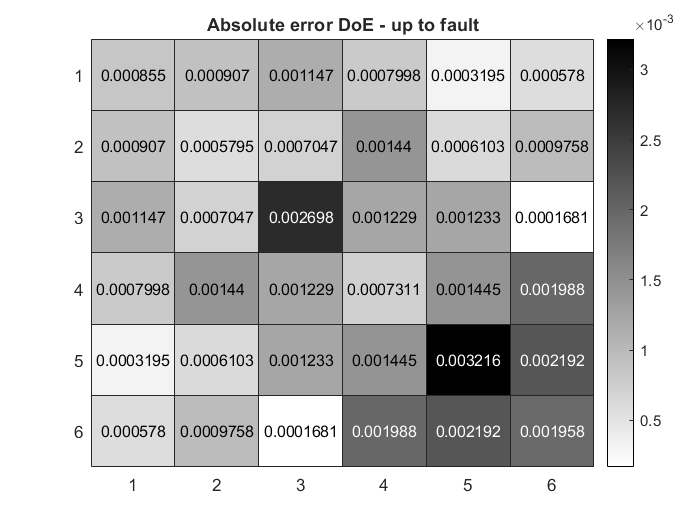

Y_hat_doe_2(:, :, 1) = [];
V_real_doe_2(:, 1) = [];
Y_hat_doe = cat(3, Y_hat_doe_1, Y_hat_doe_2);
V_real_doe = cat(2, V_real_doe_1, V_real_doe_2);
error_metrics(Y, Y_hat_doe(:, :, fault_instant-1), 'DoE - up to fault');

Froebius norm for DoE - after fault is 0.015109
Max norm for DoE - after fault is 0.0047603


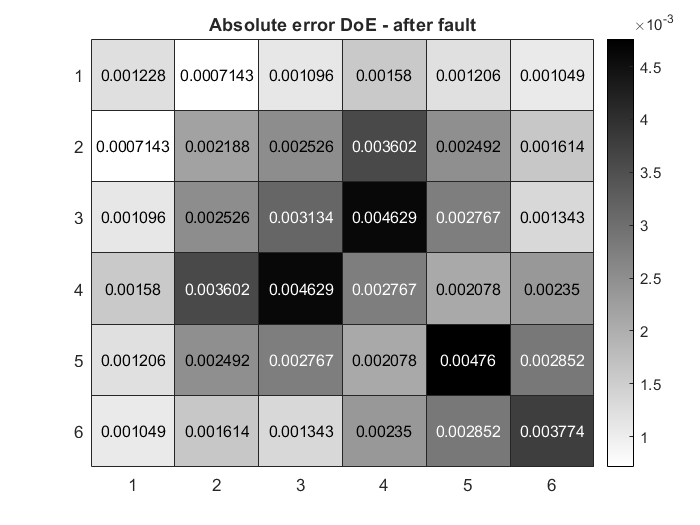

error_metrics(Y_after_fault, Y_hat_doe(:, :, end), 'DoE - after fault');

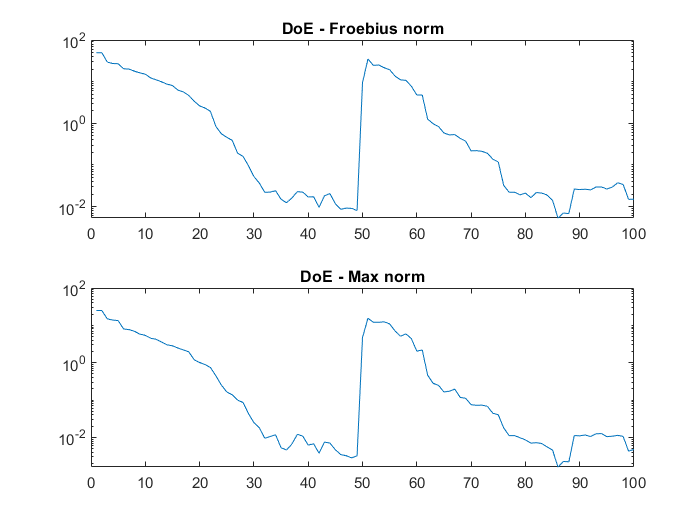

[doe_foeb, doe_max] = error_evolution(Y_real, Y_hat_doe, 'DoE');

We also investigate voltage evolution.

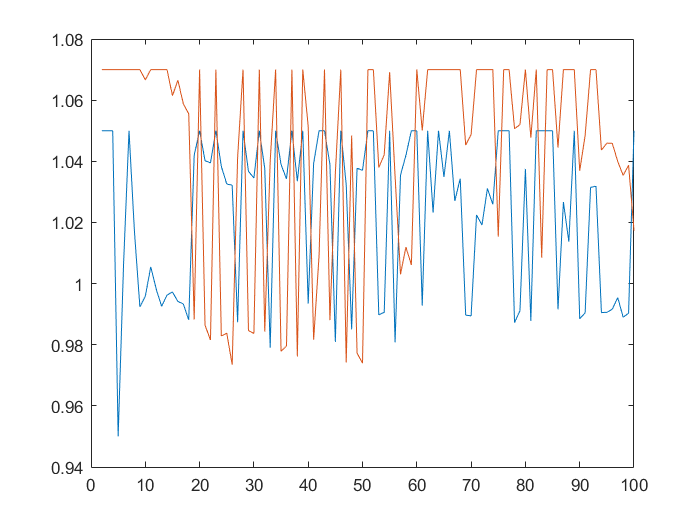

figure()
plot(2:samples, abs(V_real_doe(2:3, 2:end)));

## Comparison between methods

Finally, we compare error evolution between the two methods

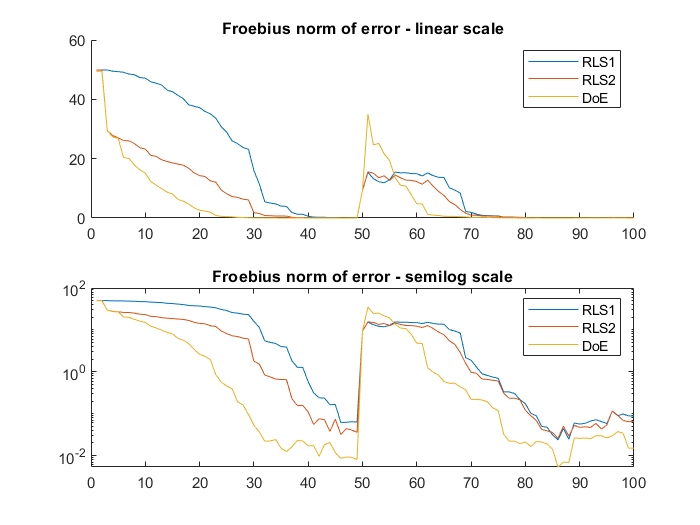

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_foeb);
plot(1:samples, rls2_foeb);
plot(1:samples, doe_foeb);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_foeb; rls2_foeb; doe_foeb]');
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - semilog scale');

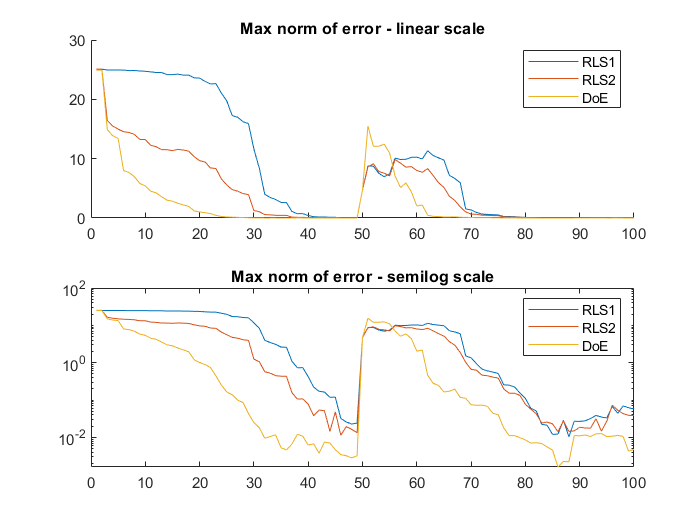

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_max);
plot(1:samples, rls2_max);
plot(1:samples, doe_max);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_max; rls2_max; doe_max]');
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - semilog scale');

As this particular test case involves a line trip, we compare the evolution of the elements involved in the episode, namely Y(2, 2), Y(2, 6) and Y(6, 6). It should be noted that they are linked by the structural constrints of the admittance matrix.

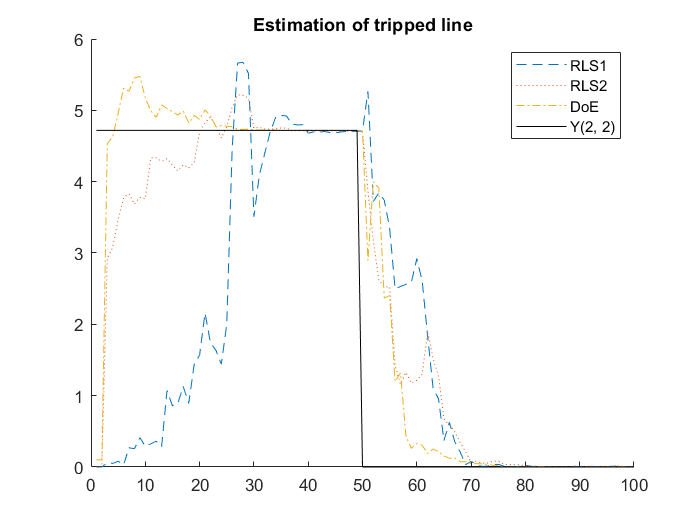

figure()
hold on
plot(1:samples, abs(squeeze(Y1_hat(2, 6, :))), '--');
plot(1:samples, abs(squeeze(Y2_hat(2, 6, :))), ':');
plot(1:samples, abs(squeeze(Y_hat_doe(2, 6, :))), '-.');
plot(1:samples, abs(squeeze(Y_real(2, 6, :))), 'Color', 'black');
hold off
legend('RLS1', 'RLS2', 'DoE', 'Y(2, 2)');
title('Estimation of tripped line');

froe_errors_without_fault = [rls1_foeb; rls2_foeb; doe_foeb]';
max_errors_without_fault = [rls1_max; rls2_max; doe_max]';
line_trip_estimation = [(1:samples)', abs(squeeze(Y1_hat(2, 6, :))), abs(squeeze(Y2_hat(2, 6, :))), abs(squeeze(Y_hat_doe(2, 6, :))), abs(squeeze(Y_real(2, 6, :)))];
writematrix(froe_errors_without_fault, 'froe_errors_with_fault.csv');
writematrix(max_errors_without_fault, 'max_errors_with_fault.csv');
writematrix(abs(V_real_doe)', 'doe_voltages_with_fault.csv');
writematrix(line_trip_estimation, 'line_trip_estimation.csv');